# Linealización entrada-estado

Partimos del sistema no lineal definido por: 


$${\dot{x} }_1 =-2\;x_{1\;} +{a\;x}_2 +\sin \;x_1$$



$${\dot{x} }_2 =-x_{2\;} \cos \left(x_1 \right)+u\;\cos \left(2x_1 \right)$$


clear; close all; clc; 

## 1. Análisis de efecto de parámetro "a"

Es de particular interés, que la dinámica del sistema dependa en gran medida de un parámetro $a$. Comenzamos explorando su efecto en el sistema 

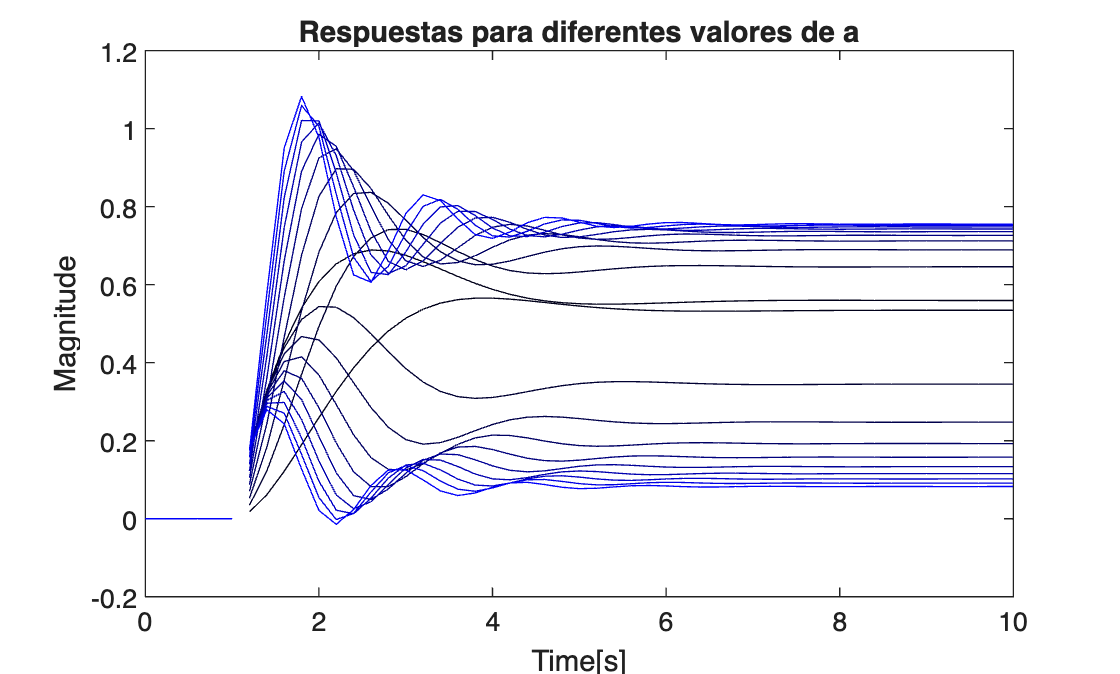

for a = 1:10
    res = sim("input_state_lin.slx"); 
    
    t = res.tout;  % Tiempo de simulación
    x = res.simout.data; % Estado
    
    % color definition 
    c = [0, 0, a * 25] / 255; 
    plot(t, x, "Color", c); 
    hold on; 
end 
title("Respuestas para diferentes valores de a"); 
xlabel("Time[s]"); ylabel("Magnitude")

hold off; 

## Linealización entrada-estado 

Proponemos una linealización de la forma $z = f(x)$ de tal forma que obtengamos un sistema LTI equivalente al sistema no lineal inicial. Para esto se propone que la sustitución rechace la no linealidad. 

% Valores iniciales 
x1_0 = 5; 
x2_0 = -10; 





